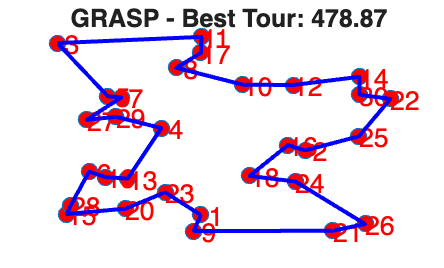

%% GRASP pro TSP
clear; clc; clf;
load ex12.mat
nr_cities = 30;

% GRASP parametry
n_iter = 100;           % Počet iterací GRASP
alpha = 0.3;            % Parametr RCL (0=deterministický, 1=random)
n_2opt = 50;            % Max počet 2-opt iterací per řešení
best_tour_grasp = [];
best_cost_grasp = inf;

% Tracking
grasp_best = Inf*ones(n_iter, 1);

%% GRASP hlavní cyklus
for iter = 1:n_iter
    
    % --- CONSTRUCTION  ---

    tour = grasp_construction(nr_cities, dist_matrix, alpha);
    cost = eval_perm(tour, dist_matrix, nr_cities);
    
    % --- LOCAL SEARCH PHASE (2-Opt) ---
    [tour_improved, cost_improved] = two_opt(tour, dist_matrix, nr_cities, n_2opt);
    
    % Uchování nejlepšího řešení
    grasp_best(iter) = cost_improved;
    if cost_improved < best_cost_grasp
        best_cost_grasp = cost_improved;
        best_tour_grasp = tour_improved;
    end
    
end


scatter(positions(:,1), positions(:,2), 'MarkerFaceColor', 'red');
hold on;
text(positions(:,1), positions(:,2), num2str((1:nr_cities)'), 'color', 'red');
plot([positions(best_tour_grasp,1); positions(1,1)], ...
     [positions(best_tour_grasp,2); positions(1,2)], 'b-', 'LineWidth', 1.5);
axis off;
title(sprintf('GRASP - Best Tour: %.2f', best_cost_grasp));

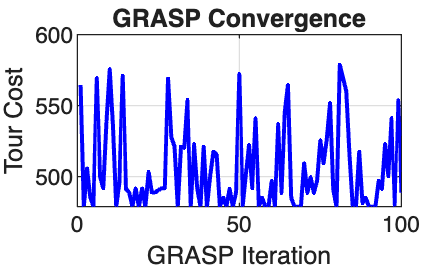


figure;
plot(1:n_iter, grasp_best, 'b-', 'LineWidth', 1.5);
xlabel('GRASP Iteration');
ylabel('Tour Cost');
title('GRASP Convergence');
grid on;



function tour = grasp_construction(n, dist_matrix, alpha)
    
    unvisited = 2:n;  
    tour = [1];
    current = 1;
    
    while ~isempty(unvisited)
        distances = dist_matrix(current, unvisited);
        
        [sorted_dist, sorted_idx] = sort(distances);
        

        min_dist = min(sorted_dist);
        max_dist = max(sorted_dist);
        threshold = min_dist + alpha * (max_dist - min_dist);
        
        rcl_mask = sorted_dist <= threshold;
        rcl_indices = sorted_idx(rcl_mask);
        
        random_idx = randi(length(rcl_indices));
        next_city = unvisited(rcl_indices(random_idx));
        
        tour = [tour, next_city];
        
        unvisited(unvisited == next_city) = [];
        current = next_city;
    end
end


function [tour_best, cost_best] = two_opt(tour, dist_matrix, nr_cities, max_iter)
    tour_best = tour;
    cost_best = eval_perm(tour_best, dist_matrix, nr_cities);
    
    for iter = 1:max_iter
        improved = false;
        
        for i = 2:nr_cities-1
            for j = i+1:nr_cities

                tour_new = tour_best;
                tour_new(i:j) = flip(tour_new(i:j));
                cost_new = eval_perm(tour_new, dist_matrix, nr_cities);
                
                if cost_new < cost_best
                    tour_best = tour_new;
                    cost_best = cost_new;
                    improved = true;
                    break;
                end
            end
            if improved
                break;
            end
        end
        
        if ~improved
            break;
        end
    end
end

%% Evaluation function
function val = eval_perm(perm, dist_matrix, nr_cities)
    val = 0;
    for i = 1:nr_cities-1
        cur_city = perm(i);
        next_city = perm(i+1);
        val = val + dist_matrix(cur_city, next_city);
    end
    val = val + dist_matrix(perm(nr_cities), perm(1));
end
